# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

Check that MATLAB can recognize the Python installation. Use `pyversion` if you are using a MATLAB version prior to R2019b.

% pyversion()
pyenv

ans =   PythonEnvironment with properties:

          Version: "3.6"
       Executable: "C:\Python36\WPy-3670\python-3.6.7.amd64\python.EXE"
          Library: "C:\Python36\WPy-3670\python-3.6.7.amd64\python36.dll"
             Home: "C:\Python36\WPy-3670\python-3.6.7.amd64"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "27384"
      ProcessName: "MATLABPyHost"

Test a simple function.

py.math.sqrt(42)

ans = 6.4807

Pass arguments using pyargs.

% py.textwrap.wrap("Hello world!",pyargs('width',2))   % errors
py.textwrap.wrap("Hello world!",pyargs('width',int8(2)))

ans =   Python list with no properties.

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

## Read weather data using Python module 

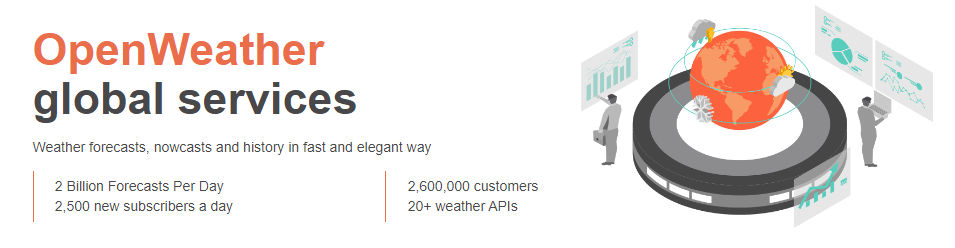

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("Boston","US",apikey.Key)

jsonData =   Python dict with no properties.

    {'coord': {'lon': -71.0598, 'lat': 42.3584}, 'weather': [{'id': 801, 'main': 'Clouds', 'description': 'few clouds', 'icon': '02d'}], 'base': 'stations', 'main': {'temp': 50.99, 'feels_like': 40.35, 'temp_min': 46.99, 'temp_max': 53.01, 'pressure': 1019, 'humidity': 49}, 'visibility': 10000, 'wind': {'speed': 12.66, 'deg': 120}, 'clouds': {'all': 20}, 'dt': 1616013601, 'sys': {'type': 1, 'id': 3486, 'country': 'US', 'sunrise': 1615978342, 'sunset': 1616021562}, 'timezone': -14400, 'id': 4930956, 'name': 'Boston', 'cod': 200}

Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 50.99, 'feels_like': 40.35, 'temp_min': 46.99, 'temp_max': 53.01, 'pressure': 1019, 'humidity': 49, 'speed': 12.66, 'deg': 120, 'lon': -71.0598, 'lat': 42.3584, 'city': 'Boston', 'current_time': '2021-03-17 16:43:12.447008'}

## Preprocess data 

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 50.9900
      feels_like: 40.3500
        temp_min: 46.9900
        temp_max: 53.0100
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
           speed: 12.6600
             deg: [1×1 py.int]
             lon: -71.0598
             lat: 42.3584
            city: [1×6 py.str]
    current_time: [1×26 py.str]

Convert the remaining python types to the desired MATLAB data types.

double(data.pressure)

ans = 1019

Perform the remaining conversions using the function below. 

convertData(data)

ans = 1×10 table
      T        P       RH     WindSpd    WindDir        deg          lon       lat        city           DateLocal      
    _____    _____    ____    _______    _______    ____________    ______    ______    ________    ____________________
    50.99    40.35    1019      49        12.66     [1×1 py.int]    -71.06    42.358    "Boston"    17-Mar-2021 16:43:12

## Handle timeseries with the weather forecast

Now let's look at the weather forecast for this week in Boston!

jsonData = py.weather.get_forecast("Boston","US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData);
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×40 py.list]
             deg: [1×40 py.list]
           speed: [1×40 py.list]
        humidity: [1×40 py.list]
        pressure: [1×40 py.list]

The type of data returned by the parsed forecast date is a **Python list**:

forecast.temp

ans =   Python list with no properties.

    [49.6, 42.94, 38.53, 36.21, 35.65, 37.83, 45.99, 51.82, 48.15, 45.27, 42.39, 33.22, 27.88, 25.61, 28.22, 31.73, 34.52, 30.99, 28.72, 27.46, 26.56, 28.24, 37.74, 46.18, 47.62, 39.67, 36.73, 35.1, 33.31, 35.26, 46.26, 51.73, 50.56, 43.32, 39.97, 37.53, 36.16, 37.92, 49.28, 54.16]

It can be converted to a matrix of doubles:

% tempForecast = double(forecast.temp)          % from an array
tempForecast = cell2mat(cell(forecast.temp))    % from a list

tempForecast =    49.6000   42.9400   38.5300   36.2100   35.6500   37.8300   45.9900   51.8200   48.1500   45.2700   42.3900   33.2200   27.8800   25.6100   28.2200   31.7300   34.5200   30.9900   28.7200   27.4600   26.5600   28.2400   37.7400   46.1800   47.6200   39.6700   36.7300   35.1000   33.3100   35.2600   46.2600   51.7300   50.5600   43.3200   39.9700   37.5300   36.1600   37.9200   49.2800   54.1600


Transform **timestamp list** from Python in **MATLAB datetime**:

foreTime = cell(forecast.current_time)

foreTime = 1×40 cell array
    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}

T = cellfun(@string,foreTime)

T = 1×40 string array
    "2021-03-17 21:00:00"    "2021-03-18 00:00:00"    "2021-03-18 03:00:00"    "2021-03-18 06:00:00"    "2021-03-18 09:00:00"    "2021-03-18 12:00:00"    "2021-03-18 15:00:00"    "2021-03-18 18:00:00"    "2021-03-18 21:00:00"    "2021-03-19 00:00:00"    "2021-03-19 03:00:00"    "2021-03-19 06:00:00"    "2021-03-19 09:00:00"    "2021-03-19 12:00:00"    "2021-03-19 15:00:00"    "2021-03-19 18:00:00"    "2021-03-19 21:00:00"    "2021-03-20 00:00:00"    "2021-03-20 03:00:00"    "2021-03-20 06:00:00"    "2021-03-20 09:00:00"    "2021-03-20 12:00:00"    "2021-03-20 15:00:00"    "2021-03-20 18:00:00"    "2021-03-20 21:00:00"    "2021-03-21 00:00:00"    "2021-03-21 03:00:00"    "2021-03-21 06:00:00"    "2021-03-21 09:00:00"    "2021-03-21 12:00:00"    "2021-03-21 15:00:00"    "2021-03-21 18:00:00"    "2021-03-21 21:00:00"    "2021-03-22 00:00:00"    "2021-03-22 03:00:00"    "2021-03-22 06:00:00"    "2021-03-22 09:00:00"    "2021-03-22 12:00:00"    "2021-03-22 15:00:00"   

Convert T in datetime

time = datetime(T)

time = 1×40 datetime array
   17-Mar-2021 21:00:00   18-Mar-2021 00:00:00   18-Mar-2021 03:00:00   18-Mar-2021 06:00:00   18-Mar-2021 09:00:00   18-Mar-2021 12:00:00   18-Mar-2021 15:00:00   18-Mar-2021 18:00:00   18-Mar-2021 21:00:00   19-Mar-2021 00:00:00   19-Mar-2021 03:00:00   19-Mar-2021 06:00:00   19-Mar-2021 09:00:00   19-Mar-2021 12:00:00   19-Mar-2021 15:00:00   19-Mar-2021 18:00:00   19-Mar-2021 21:00:00   20-Mar-2021 00:00:00   20-Mar-2021 03:00:00   20-Mar-2021 06:00:00   20-Mar-2021 09:00:00   20-Mar-2021 12:00:00   20-Mar-2021 15:00:00   20-Mar-2021 18:00:00   20-Mar-2021 21:00:00   21-Mar-2021 00:00:00   21-Mar-2021 03:00:00   21-Mar-2021 06:00:00   21-Mar-2021 09:00:00   21-Mar-2021 12:00:00   21-Mar-2021 15:00:00   21-Mar-2021 18:00:00   21-Mar-2021 21:00:00   22-Mar-2021 00:00:00   22-Mar-2021 03:00:00   22-Mar-2021 06:00:00   22-Mar-2021 09:00:00   22-Mar-2021 12:00:00   22-Mar-2021 15:00:00   22-Mar-2021 18:00:00

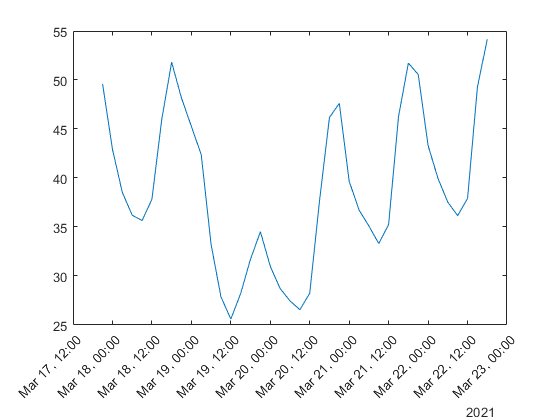

plot(time,tempForecast)
xtickangle(45)

## Preprocess data using MATLAB live task

Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

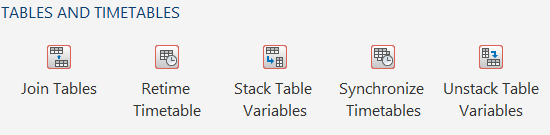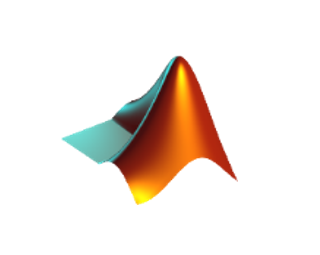

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'})

foreTemp = 40×1 timetable
            Time            Temperature
    ____________________    ___________
    17-Mar-2021 21:00:00        49.6   
    18-Mar-2021 00:00:00       42.94   
    18-Mar-2021 03:00:00       38.53   
    18-Mar-2021 06:00:00       36.21   
    18-Mar-2021 09:00:00       35.65   
    18-Mar-2021 12:00:00       37.83   
    18-Mar-2021 15:00:00       45.99   
    18-Mar-2021 18:00:00       51.82   
    18-Mar-2021 21:00:00       48.15   
    19-Mar-2021 00:00:00       45.27   
    19-Mar-2021 03:00:00       42.39   
    19-Mar-2021 06:00:00       33.22   
    19-Mar-2021 09:00:00       27.88   
    19-Mar-2021 12:00:00       25.61   
    19-Mar-2021 15:0

% Retime timetable
newTimetable = retime(foreTemp,'regular','spline','TimeStep',hours(1))

newTimetable = 118×1 timetable
            Time            Temperature
    ____________________    ___________
    17-Mar-2021 21:00:00        49.6   
    17-Mar-2021 22:00:00      47.123   
    17-Mar-2021 23:00:00      44.904   
    18-Mar-2021 00:00:00       42.94   
    18-Mar-2021 01:00:00      41.226   
    18-Mar-2021 02:00:00      39.757   
    18-Mar-2021 03:00:00       38.53   
    18-Mar-2021 04:00:00      37.538   
    18-Mar-2021 05:00:00      36.769   
    18-Mar-2021 06:00:00       36.21   
    18-Mar-2021 07:00:00      35.846   
    18-Mar-2021 08:00:00      35.664   
    18-Mar-2021 09:00:00       35.65   
    18-Mar-2021 10:00:00       35.84   
    18-Mar-2021

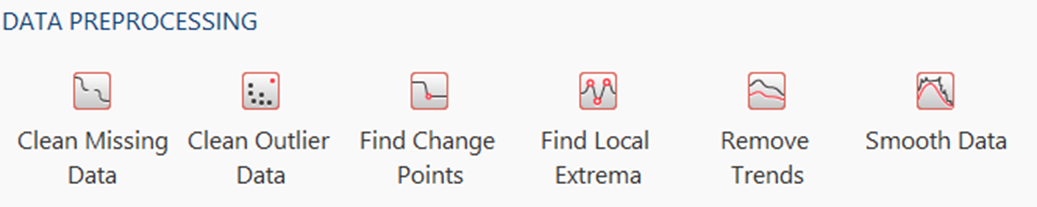

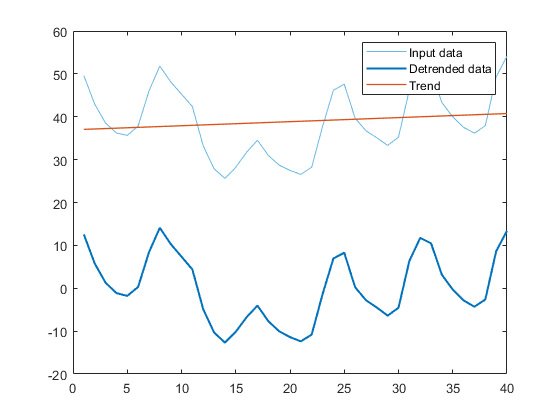

% Remove trend from data
detrendedData = detrend(tempForecast);

% Display results
clf
plot(tempForecast,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(tempForecast-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

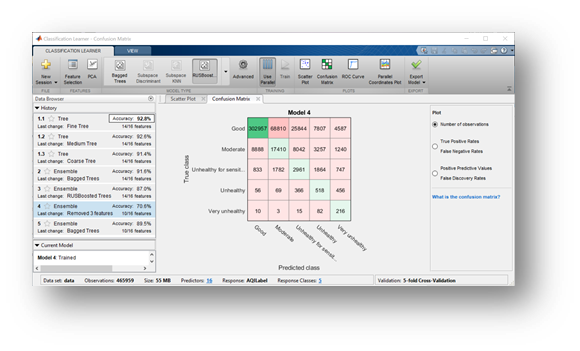

Use a function (`prepData.m`) to convert and prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city        StateName        T       P       DP      RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    _____    ____    _____    __    _______    _______    ____    __    __
    17-Mar-2021 16:43:12    "Boston"    Massachusetts    50.99    1019    32.63    49      120       12.66     2021    3     17

Use the model to predict the air quality for the new weather data.

'*airQualModel.mat*' is a pre-trained Bagged Classification Tree/ "Random Forest" classification network. The network was trained using a large data set stored on a local HDFS cluster (~1TB of historical weather data) and required the use of the "tall" MATLAB datatype.  The model was saved as a *.mat file for use in predicting air quality in this demonstration. 

load airQualModel 

airQual = predict(model,currentData)

airQual = categorical
     Good 

## Share prediction code

Create a function with these steps to be called in the Python environment.

edit("predictAirQual.m")

See `CallMATLABfromPython.ipynb`

## Reload Python module

Reload *weather.py *after modifications:

clear classes

mod = py.importlib.import_module('weather'); 
py.importlib.reload(mod); 

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/releases/R2015b/matlab/matlab_external/call-modified-python-module.html)

**Helper Functions**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end

Subsequential calls of the `weather.py` functions in a single MATLAB function:

function [time,tempForecast] = callWeatherFromPython(city,apikey)
    switch city
        case "Boston" 
            country = "US";
        case "Paris"
            country = "France";
        case "Moscow"
            country = "Russia";
    end
    jsonData = py.weather.get_forecast(city,country,apikey);
    forecastData = py.weather.parse_forecast_json(jsonData);
    forecast = struct(forecastData);
    tempForecast = double(forecast.temp);
    foreTime = cell(forecast.current_time);
    T = cellfun(@string,foreTime);
    time = datetime(T);
end